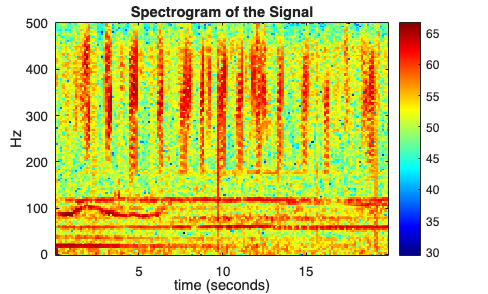

clear
close all

addpath '/Users/corinnepickering/Desktop/Thode_lab/Ulysses/source/deps'%path to add compute_directional_metrics.m function

%%%Standard_Spectorgram%%%
fname = "soundsampDA23A0T20230717T000000.gsi_20230717T075959.mat";
data = load(fname);
x = data.x; % Assuming 'data' is the variable containing the signal in the loaded .mat file
nfft = 256; % Define the number of FFT points
window = hamming(nfft); % Define the window for the spectrogram
noverlap = nfft/2; % Define the number of overlapping samples
[s,f,t] = spectrogram(x(:,1),window,noverlap,nfft,data.Fs);

Pdb = 10 * log10(abs(s)); % magnitude and convert db
imagesc(t,f,Pdb); % re-orient frequency axis 
axis xy
xlabel("time (seconds)");% time
ylabel("Hz"); % frequency
colorbar
colormap("jet")
%soundsc(x(:,1),2 * data.Fs) % play sound aloud
title("Spectrogram of the Signal");




%%%%compute_directional_metrics.m%%%%%%%%%%%%%%%%%%%
metric_type{1}='Azimuth';
metric_type{2}='ItoERatio';
param.sec_avg='0';
     param.climm='[0 360]'; %compass heading lims
     param.brefa='0'; %barring referance angle
%     param.alg=Batch_vars.alg;
     param.phase_calibration='Arctic5G_2014';
     param.instrument{1} = 'DASAR_DASAR-omnisensor';
     param.instrument{2} = 'DASAR_DASAR-Xsensor';
     param.instrument{3} = 'DASAR_DASAR-Ysensor';
%     '_VS-209-omnisensor'; needs to start with '_' and end with 'sensor'
%           Each channel needs its own string.
[TT,FF,output_array,PdB]=compute_directional_metrics(x',metric_type, ...
   data.Fs,nfft, 0.5, param);

Spectrogram channel 1
Spectrogram channel 2
Spectrogram channel 3


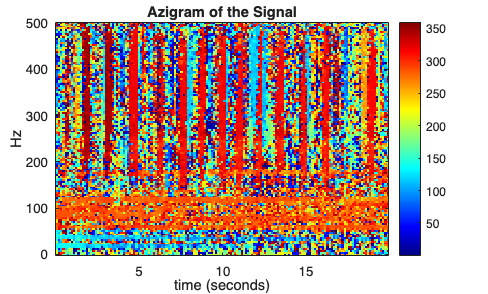

figure;
imagesc(TT,FF,output_array{1}); % re-orient frequency axis 
axis xy
xlabel("time (seconds)");% time
ylabel("Hz"); % frequency
colorbar
colormap("jet")
%soundsc(x(:,1),2 * data.Fs) % play sound aloud
title("Azigram of the Signal");


% x:  array of vector data, each row is a separate channel
% metric_type{Iwant}:'Azimuth','Elevation','ItoERatio','KEtoPERatio',
%       'IntensityPhase', 'Polarization','AdditiveBeamforming'
%           metric_type can also be a string.
%           If a cell array output_array will be a cell array
%           If 'wavelet' appended to metric_type string, will use wavelets
%          
% Fs: sampling rate in Hz
% Nfft: FFT size used to compute frequency bin size
% ovlap: fraction ovlap when computing spectrograms
% reactive_flag:  if true, compute reactive intensity.  Vector same size as
%
% param:
%     param.sec_avg=(Batch_vars.sec_avg);
%     param.climm=(Batch_vars.climm);
%     param.brefa=(Batch_vars.brefa);
%     param.alg=Batch_vars.alg;
%     param.phase_calibration='Arctic5G_2014';
%     param.instrument{1} = 'drifterM35sensor' or 'DIFARsensor' or
%     '_VS-209-omnisensor'; needs to start with '_' and end with 'sensor'
%           Each channel needs its own string.
%     param.myfile:  Name of file that contains time and instrument
%       identity.  Typically used to determine brefa and other instrument
%       orientation information.
% filetype: dead variable, can be empty
%
% Output:
%  TT,FF, output_array{Nmetric}:  TT vector of times and FF vector of Hz for
%               output_array grid, one for each value in metric_type.
%               If 'polarization' is a metric, output_array{}[freq times metric] will have
%               three dimensions, with third dimension being Stokes metric.
%
%  PdB: power spectral density of pressure autospectrum
%  param:  altered parameters of input param
%  Ix, Iy, Iz:  x and y complex intensity